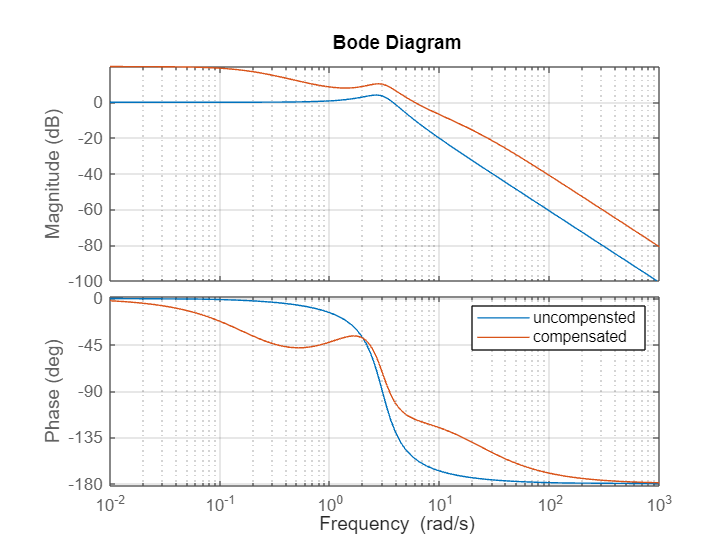

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT

% Case 1: G1(s) = 9/(s^2 + 4 s + 9)
s = tf('s');
G1 = 9/(s^2 + 2*s+9);%%open loopTf for uncompensated sytem

% Proposed compensators
C_lead = 10*(s+2)/(s+18);%%lead comaparator
C_lag  = (s+2)/(s+0.2);
C_T= C_lead * C_lag;%%lead and lag in cascade

% Closed-loop (unity feedback)
T1 = feedback(C_T * G1, 1);

% bode plot for uncompenated system and compensated system
figure;
bode(G1, C_T*G1); 
legend('uncompensted','compensated');
grid on;

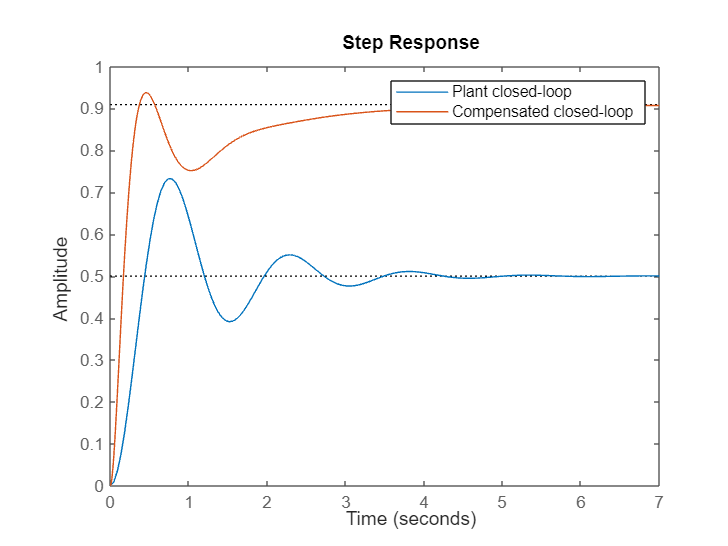

Step info for compensated case 1:


         RiseTime: 0.2418
    TransientTime: 3.2608
     SettlingTime: 3.2608
      SettlingMin: 0.7517
      SettlingMax: 0.9377
        Overshoot: 3.1426
       Undershoot: 0
             Peak: 0.9377
         PeakTime: 0.4559



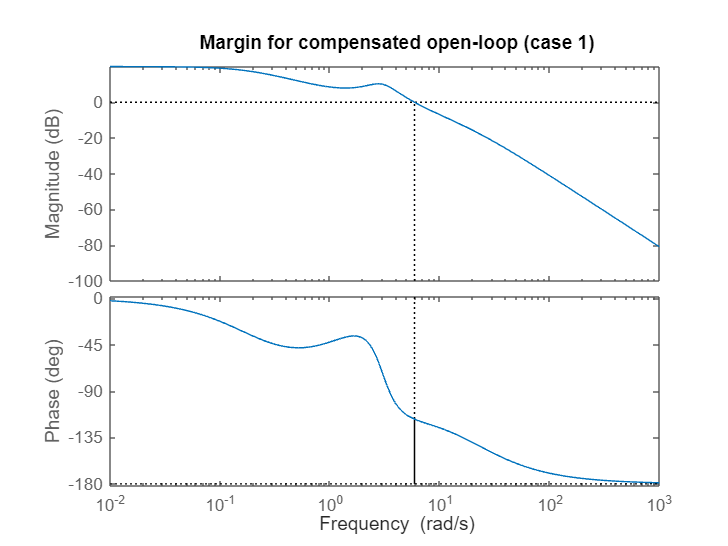

%%step polots for uncompensatedand fully_compensted system
figure; 
step(G1/(1+G1), T); 
legend('Plant closed-loop','Compensated closed-loop');